# Lagrange-Polynominterpolation: Darstellung in  Langrange- und in monomialer Basis

Seien  $x_j$, $j=0,\ldots,n$,  die Tschebyscheff -Stützstellen  im Intervall $[0,1]$ (siehe Buch).

Für einen Translationsparameter $d \geq 0$ betrachten wir die "verschobene'' Interpolationsaufgabe: $P_n \in \Pi_n$, so dass

          
$$P_n(x_j+d)=3 \sin (3 x_j),  \quad j=0,\ldots,n.$$


Die eindeutige Lösung dieser Aufgabe ist das Lagrange-Interpolationspolynom zu den Daten $(x_j+d, 3 \sin(x_j))$, $j=0,\ldots,n.$ Dieses Polynom hat die Translationsinvarianz-Eigenschaft (siehe Buch):

        
$$P(f_d|x_0+d,\ldots,x_n+d)(x+d)=P(f_0|x_0,\ldots,x_n)(x), \quad \text{mit}~~f_d(x_j+d):=3 \sin(3 x_j).$$
 

 Beachte, dass mit dieser Stützstellenverteilung die Kondition des Interpolationproblems (bzgl. Störungen in den Daten $f_d(x_j+d)$), unabhängig von $d$,  gut ist: kleine Störungen in den Daten bewirken nur kleine Änderungen des Interpolationspolynoms. Dieses Interpolationspolynom wird in der Lagrange-Basis  $\ell_{j,n}(\cdot),~j=0,\ldots, n$, (siehe Buch)  und in der monomialen Basis dargestellt:

    $P(f_d|x_0+d,\ldots,x_n+d)(x)=\sum_{j=0}^n f_d(x_j+d) \ell_{j,n}(x)$     und  $P(f_d|x_0,\ldots,x_n)(x)=\sum_{j=0}^n a_j x^j$.

Wir wählen den Polynomgrad $n$ und den Verschiebungsparameter $d$.   

n=8

n = 8

d=10

d = 100000

Die Datenpunkte werden generiert und geplottet.

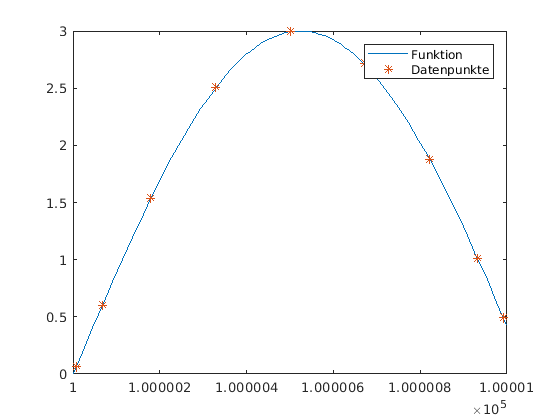

[Knoten,Daten]=Datengenerierung(n,d);
fplot(@(x) 3*sin(3*(x-d)),[d,d+1]);
hold on;
plot(Knoten,Daten,'*');
legend('Funktion','Datenpunkte');
hold off;

Die Koeffizienten $a_j,\, j=0,\ldots,n$, der Darstellung in der monomialen Basis werden über das Lösen eines Gleichungssystems mit einer Vandermonde-Matrix bestimmt (siehe Buch). Danach werden beide Darstellungen auf einem äquidistanten Gitter ausgewertet und geplottet. Beachte, dass ohne Rundungsfehler die zwei Darstellungen dieselben Ergebnisse liefern würden.

a= BestimmungKoeffizienten(Knoten,Daten);

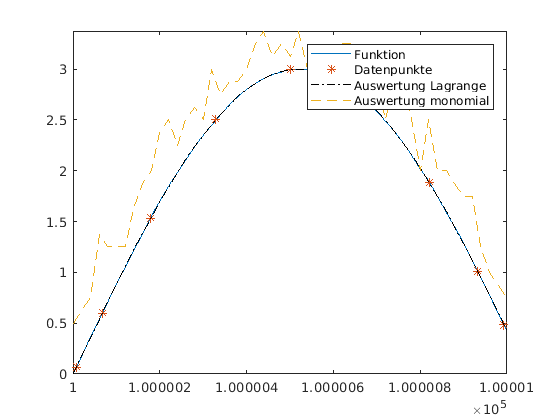

figure(2)
mplot=51;
x=linspace(d, d+1, mplot);
PolynomLagrange=zeros(mplot,1);
PolynomMonom=zeros(mplot,1);
for i=1:mplot
    PolynomLagrange(i)=lagrange(x(i),Knoten,Daten);
    PolynomMonom(i)=monomial(a,x(i));
end
fplot(@(x) 3*sin(3*(x-d)),[d,d+1]);
hold on;
plot(Knoten,Daten,'*');
plot(x,PolynomLagrange,'-.k');
plot(x,PolynomMonom,'--');
legend('Funktion','Datenpunkte','Auswertung Lagrange','Auswertung monomial');
hold off;

# Aktivität:

Variieren Sie $n$ (Polynomgrad), z.B. $n\in\{4,6,8,10\}$, und $d$ (Intervallverschiebung), z.B. $d\in \{10,10^3,10^4,10^5\}$ und beobachten Sie die Effekte der Rundungsfehlern in den zwei Darstellungen.

function [Knoten,Daten]=Datengenerierung(n,d)
Knoten=zeros(n+1,1);
Daten=zeros(n+1,1);
for i=0:n
    Knoten(i+1)=0.5-0.5*cos(pi*(2*i+1)/(2*n+2))+d;
    Daten(i+1)=3*sin(3*(Knoten(i+1)-d));
end
end

function a=BestimmungKoeffizienten(Knoten,Daten)
m=length(Knoten);
V=zeros(m,m);
for i=1:m
    for j=1:m
        V(i,j)=(Knoten(i))^(j-1);
    end
end
a=V\Daten;  
end

function y=lagrange(x,Knoten,Daten)
% Diese Funktion wertet das Interpolationspolynom in der Lagrange-Darstellung an der Stelle x aus.
    m=length(Knoten);
    L=ones(m,1);
    for i=1:m
        for k=1:m
            if (i~=k)
                L(i)=L(i)*(x-Knoten(k))/(Knoten(i)-Knoten(k));
            end
        end
    end
    y=Daten'*L;
end

function y=monomial(a,x)
% Diese Funktion wertet das Interpolationspolynom in der monomialen Darstellung an der Stelle x aus.
    y=polyval(flip(a),x);
end